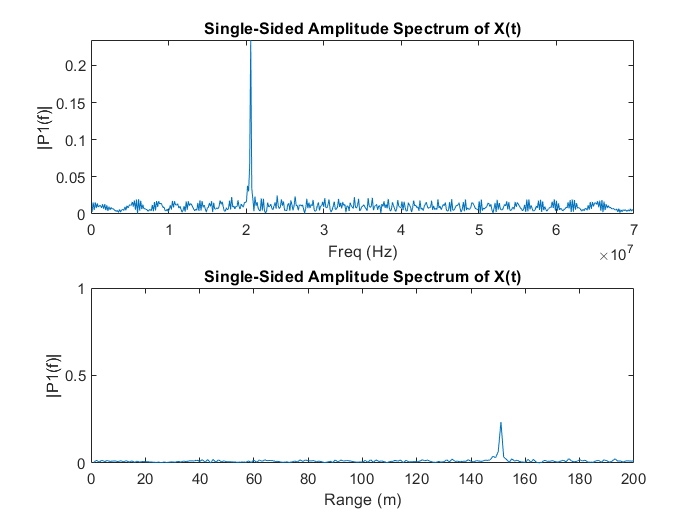

clear all;
close all;
clc;

%% Radar Specifications 
%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Frequency of operation = 77GHz
% Max Range = 200m
% Range Resolution = 1 m
% Max Velocity = 100 m/s
%%%%%%%%%%%%%%%%%%%%%%%%%%%

%speed of light = 3e8
%% User Defined Range and Velocity of target
% *%TODO* :
% define the target's initial position and velocity. Note : Velocity
% remains contant

InitialPosition = 150;%m
Velocity = -50; % m/s
c = 3e8;
RangeResolution = 1;% m
RangeMax = 200; % m

%% FMCW Waveform Generation

% *%TODO* :
%Design the FMCW waveform by giving the specs of each of its parameters.
% Calculate the Bandwidth (Bsweep), Chirp Time (Tchirp) and Slope (slope) of the FMCW
% chirp using the requirements above.
Bsweep = c /(2* RangeResolution);
Tchirp = 5.5*2* RangeMax /c;
slope = Bsweep/Tchirp;

%Operating carrier frequency of Radar 
fc = 77e9;             %carrier freq

                                                          
%The number of chirps in one sequence. Its ideal to have 2^ value for the ease of running the FFT
%for Doppler Estimation. 
Nd = 128;                   % #of doppler cells OR #of sent periods % number of chirps

%The number of samples on each chirp. 
Nr = 1024;                  %for length of time OR # of range cells

fs = Nr/Tchirp;
% Timestamp for running the displacement scenario for every sample on each
% chirp
t = linspace(0,Nd*Tchirp,Nr*Nd); %total time for samples


%Creating the vectors for Tx, Rx and Mix based on the total samples input.
Tx = zeros(1,length(t)); %transmitted signal
Rx = zeros(1,length(t)); %received signal
Mix = zeros(1,length(t)); %beat signal

%Similar vectors for range_covered and time delay.
r_t = zeros(1,length(t));
td = zeros(1,length(t));


%% Signal generation and Moving Target simulation
% Running the radar scenario over the time. 

for i=1:length(t)         
    % *%TODO* :
    %For each time stamp update the Range of the Target for constant velocity. 
    r_t(i)= InitialPosition + Velocity * i * Tchirp/Nr;
    td(i) = 2* r_t(i)/c;
    % *%TODO* :
    %For each time sample we need update the transmitted and
    %received signal. 
    
    Tx(i) = cos(2*pi*(fc*i*(Tchirp/Nr) + slope* ((i*Tchirp/Nr)^2)/2));
    Rx(i) = cos(2*pi*(fc*(i*(Tchirp/Nr)-td(i)) + slope* (((i*Tchirp/Nr)-td(i))^2)/2));
end 
    % *%TODO* :
    %Now by mixing the Transmit and Receive generate the beat signal
    %This is done by element wise matrix multiplication of Transmit and
    %Receiver Signal
    Mix = Tx.*Rx;

    
%% RANGE MEASUREMENT

 % *%TODO* :
%reshape the vector into Nr*Nd array. Nr and Nd here would also define the size of
%Range and Doppler FFT respectively.
 X =   reshape(Mix, [Nr, Nd]);
 % *%TODO* :
%run the FFT on the beat signal along the range bins dimension (Nr) 
signal_fft = fft(X,Nr);
%signal_fft = fftshift(signal_fft);

% *%TODO* :
% Take the absolute value of FFT output and normalize.
signal_fft = abs(signal_fft/Nr);

% *%TODO* :
% Output of FFT is double sided signal, but we are interested in only one side of the spectrum.
% Hence we throw out half of the samples.
signal_fft  = signal_fft(1:Nr/2); 
%% plotting the range
figure ('Name','Range from First FFT')
subplot(2,1,1)

% *%TODO* :
% plot FFT output 
%plot(signal_fft); grid minor 
f= fs* (1:Nr/2)/Nr;
plot(f,signal_fft) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('Freq (Hz)')
ylabel('|P1(f)|')

subplot(2,1,2)
RangeCal = f.*c*(Tchirp)/(2*Bsweep);
plot(RangeCal,signal_fft) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('Range (m)')
ylabel('|P1(f)|')
axis ([0 200 0 1]);

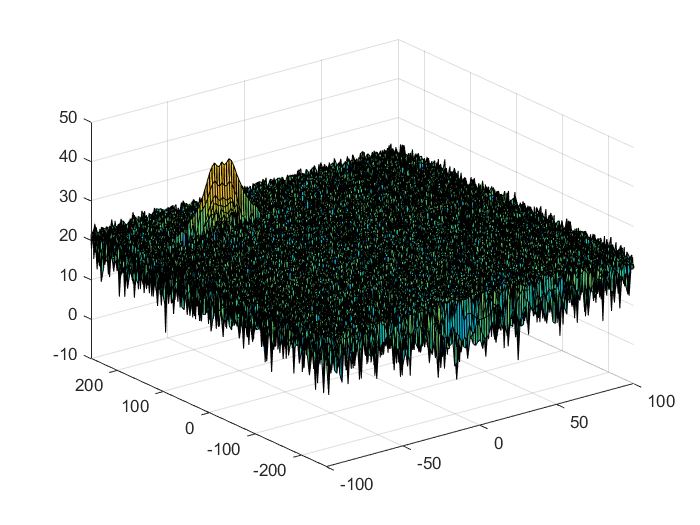



%% RANGE DOPPLER RESPONSE
% The 2D FFT implementation is already provided here. This will run a 2DFFT
% on the mixed signal (beat signal) output and generate a range doppler
% map.You will implement CFAR on the generated RDM


% Range Doppler Map Generation.

% The output of the 2D FFT is an image that has reponse in the range and
% doppler FFT bins. So, it is important to convert the axis from bin sizes
% to range and doppler based on their Max values.

Mix=reshape(Mix,[Nr,Nd]);

% 2D FFT using the FFT size for both dimensions.
sig_fft2 = fft2(Mix,Nr,Nd);

% Taking just one side of signal from Range dimension.
sig_fft2 = sig_fft2(1:Nr/2,1:Nd);
sig_fft2 = fftshift (sig_fft2);
RDM = abs(sig_fft2);
RDM = 10*log10(RDM) ;

%use the surf function to plot the output of 2DFFT and to show axis in both
%dimensions
doppler_axis = linspace(-100,100,Nd);
range_axis = linspace(-200,200,Nr/2)*((Nr/2)/400);
figure,surf(doppler_axis,range_axis,RDM);


%% CFAR implementation
% % Determine the number of Training cells for each dimension Tr and Td. Similarly, pick the number of guard cells Gr and Gd.
% % Slide the Cell Under Test (CUT) across the complete cell matrix
% % Select the grid that includes the training, guard and test cells. Grid Size = (2Tr+2Gr+1)(2Td+2Gd+1).
% % The total number of cells in the guard region and cell under test. (2Gr+1)(2Gd+1).
% % This gives the Training Cells : (2Tr+2Gr+1)(2Td+2Gd+1) - (2Gr+1)(2Gd+1)
% % Measure and average the noise across all the training cells. This gives the threshold
% % Add the offset (if in signal strength in dB) to the threshold to keep the false alarm to the minimum.
% % Determine the signal level at the Cell Under Test.
% % If the CUT signal level is greater than the Threshold, assign a value of 1, else equate it to zero.
% % Since the cell under test are not located at the edges, due to the training cells occupying the edges, we suppress the edges to zero. Any cell value that is neither 1 nor a 0, assign it a zero.
%Slide Window through the complete Range Doppler Map

% *%TODO* :
%Select the number of Training Cells in both the dimensions.
Tr = 10;
Td = 8;

% *%TODO* :
%Select the number of Guard Cells in both dimensions around the Cell under 
%test (CUT) for accurate estimation

Gr = 4;
Gd = 4;

TotalTrainingCells = (Tr+Tr+Gr+Gr+1)* (Td+Td+Gd+Gd+1);
% *%TODO* :
% offset the threshold by SNR value in dB
offset = 6;

% *%TODO* :
%Create a vector to store noise_level for each iteration on training cells
noise_level = zeros(1,1);


% *%TODO* :
%design a loop such that it slides the CUT across range doppler map by
%giving margins at the edges for Training and Guard Cells.
%For every iteration sum the signal level within all the training
%cells. To sum convert the value from logarithmic to linear using db2pow
%function. Average the summed values for all of the training
%cells used. After averaging convert it back to logarithimic using pow2db.
%Further add the offset to it to determine the threshold. Next, compare the
%signal under CUT with this threshold. If the CUT level > threshold assign
%it a value of 1, else equate it to 0.
tic
[S1, S2]=size(RDM)

S1 = 512

S2 = 128

RDM_out = zeros(S1,S2);
    for curr_range = Tr+Gr+1: S1-(Tr+Gr)
        for curr_doppler = Td+Gd+1: S2-(Td+Gd)
        
            CUT = db2pow(RDM(curr_range,curr_doppler));% cell under test
            % Calculate Noise threshold
             SumAll = db2pow(RDM(curr_range-Tr-Gr:curr_range+Tr+Gr,curr_doppler-Td-Gd:curr_doppler+Td+Gd));
             SumGuard = db2pow(RDM(curr_range-Gr:curr_range+Gr,curr_doppler-Gd:curr_doppler+Gd));
             SumAllcells = sum(SumAll,'all');
             SumGuardcells = sum(SumGuard,'all');
             AvgNoise = (SumAllcells - SumGuardcells - CUT)/TotalTrainingCells;
            %sprintf('%d, %d \n',curr_range,curr_doppler);
            noise_level(curr_range,curr_doppler) = pow2db(AvgNoise);
            if (RDM(curr_range,curr_doppler)>(noise_level(curr_range,curr_doppler)+offset))
                RDM_out(curr_range,curr_doppler) = 1;
            else
                RDM_out(curr_range,curr_doppler) = 0;    
            end
        end
    end
toc

Elapsed time is 4.022013 seconds.


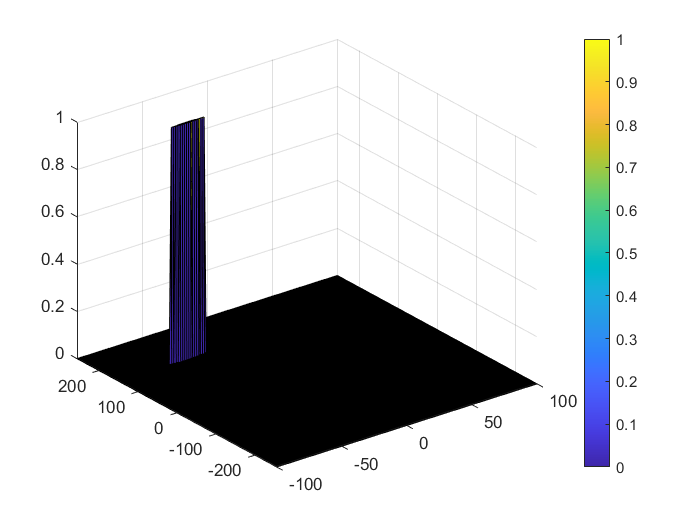

sprintf('%d \n',toc);
   % Use RDM[x,y] as the matrix from the output of 2D FFT for implementing
   % CFAR





% *%TODO* :
% The process above will generate a thresholded block, which is smaller 
%than the Range Doppler Map as the CUT cannot be located at the edges of
%matrix. Hence,few cells will not be thresholded. To keep the map size same
% set those values to 0. 
 








% *%TODO* :
%display the CFAR output using the Surf function like we did for Range
%Doppler Response output.
figure,surf(doppler_axis,range_axis,RDM_out);
colorbar;